# Initial setup

Configure the working environment, resolve project root paths, and add source directory.

clear; clc; close all;
rng(42);

thisDir = fileparts(mfilename("fullpath"));
if isempty(thisDir)
    thisDir = pwd;
end

if isfolder(fullfile(thisDir, "data"))
    projectRoot = thisDir;
elseif isfolder(fullfile(thisDir, "..", "data"))
    projectRoot = fullfile(thisDir, "..");
else
    projectRoot = pwd;
end

dataFolder = fullfile(projectRoot, "data");
if ~isfolder(dataFolder)
    error("Data folder not found at %s", dataFolder);
end

addpath(fullfile(projectRoot, "src"));

## Select zone for evaluation

Specify zone to benchmark between LSTM and tabular regression models.

zoneId = 9;  % Zone 214 Trieste
fprintf("Benchmarking Zone: %d\n", zoneId);

Benchmarking Zone: 9



zoneData = loadZoneData(dataFolder, zoneId);

Zone "Zone_214_Trieste" loaded: 2784 rows (58 complete days, 48 steps/day).
Day breakdown: 41 working days (mean: 136.9 kWh), 17 non-working days (mean: 94.8 kWh).
Seasonal clusters identified (4 clusters):
  Cluster 1: 2023-02-15 (Wed) to 2023-02-28 (Tue) (14 days)
  Cluster 2: 2023-05-31 (Wed) to 2023-06-15 (Thu) (16 days)
  Cluster 3: 2023-07-12 (Wed) to 2023-07-25 (Tue) (14 days)
  Cluster 4: 2023-09-27 (Wed) to 2023-10-10 (Tue) (14 days)



hours = hour(zoneData.datetime) + minute(zoneData.datetime)/60;
zoneData.cosHour = cos(2 * pi * hours / 24);
zoneData.sinHour = sin(2 * pi * hours / 24);

## Load trained model artifacts from disk

Find the latest trained LSTM and Regression Learner models for the selected zone.

windowSize = 48;
targetName = "AAC_energy";

lstmDir = fullfile(projectRoot, "models", "LSTM", sprintf("Zone%d", zoneId));
lstmFiles = dir(fullfile(lstmDir, "*.mat"));
if isempty(lstmFiles)
    error("No LSTM model found in %s. Run LSTM.mlx first.", lstmDir);
end
[~, latestLstmIdx] = max([lstmFiles.datenum]);
lstmPath = fullfile(lstmDir, lstmFiles(latestLstmIdx).name);
lstmArtifact = load(lstmPath);
fprintf("Loaded LSTM: %s\n", lstmFiles(latestLstmIdx).name);

Loaded LSTM: LSTM_Zone9_RMSE57.2_20260908_2320.mat



regDir = fullfile(projectRoot, "models", "RegressionLearner", sprintf("Zone%d", zoneId));
regFiles = dir(fullfile(regDir, "*.mat"));
if isempty(regFiles)
    error("No Regression Learner model found in %s. Run RegressionLearner.mlx first.", regDir);
end
[~, latestRegIdx] = max([regFiles.datenum]);
regPath = fullfile(regDir, regFiles(latestRegIdx).name);
regArtifact = load(regPath);
fprintf("Loaded Regression Model: %s\n", regFiles(latestRegIdx).name);

Loaded Regression Model: BaggedTrees_Zone9_RMSE57.7_20260913_2209.mat


## Prepare test data with strict temporal parity

Extract tabular and sequential test partitions matching the exact same timestamps.

[trainTable, ~, testTable, normParamsReg] = prepareTabularData(zoneData, windowSize, targetName);

Tabular split completed: 1824 train, 384 val, 384 test samples.


[~, ~, testDataLSTM, normParamsLSTM] = splitZoneData(zoneData, windowSize, lstmArtifact.predictorNames, targetName);

Split completed: 1824 train, 384 val, 384 test samples.



if ~isequal(testTable.datetime, testDataLSTM.timestamps)
    error("benchmarkModelsEvaluation:timestampMismatch", ...
        "Tabular and LSTM test timestamps do not match perfectly.");
end

yTest = testTable.(targetName);
meanTarget = mean(yTest);
numTestSamples = numel(yTest);
fprintf("Test set verified: %d contiguous observations.\n", numTestSamples);

Test set verified: 384 contiguous observations.


## Generate predictions from all candidate approaches

Lazy persistence baseline: predict next step using the previous half-hour value (lag 1)

yPredLazy = testTable.lag1_energy;

% Tabular Regression model prediction
XTestReg = testTable(:, regArtifact.predictorNames);
yPredReg = predict(regArtifact.baggedTreesModel, XTestReg);

% LSTM neural network prediction
yPredLSTMNorm = minibatchpredict(lstmArtifact.LSTMnet, testDataLSTM.X, SequencePaddingDirection="left");
yPredLSTM = yPredLSTMNorm .* normParamsLSTM.sigmaTarget + normParamsLSTM.muTarget;

## Compute comprehensive evaluation metrics (ASHRAE Guideline 14)

Compute Root Mean Squared Error

rmseLazy = rmse(yPredLazy, yTest);
rmseReg  = rmse(yPredReg, yTest);
rmseLSTM = rmse(yPredLSTM, yTest);

% Compute Mean Absolute Error
maeLazy = mean(abs(yPredLazy - yTest));
maeReg  = mean(abs(yPredReg - yTest));
maeLSTM = mean(abs(yPredLSTM - yTest));

% Compute Coefficient of Variation of RMSE (CV(RMSE))
cvLazy = (rmseLazy / meanTarget) * 100;
cvReg  = (rmseReg / meanTarget) * 100;
cvLSTM = (rmseLSTM / meanTarget) * 100;

% Compute relative error reduction over the persistence baseline
impReg  = (1 - rmseReg / rmseLazy) * 100;
impLSTM = (1 - rmseLSTM / rmseLazy) * 100;

benchmarkTable = table( ...
    ["Lazy Persistence (t-1)"; "Bagged Trees Ensemble"; "LSTM Recurrent Network"], ...
    [rmseLazy; rmseReg; rmseLSTM], ...
    [maeLazy; maeReg; maeLSTM], ...
    [cvLazy; cvReg; cvLSTM], ...
    [0.0; impReg; impLSTM], ...
    VariableNames=["Model", "RMSE_kWh", "MAE_kWh", "CV_RMSE_pct", "Improvement_pct"]);
disp(benchmarkTable)

             Model              RMSE_kWh    MAE_kWh    CV_RMSE_pct    Improvement_pct
    ________________________    ________    _______    ___________    _______________

    "Lazy Persistence (t-1)"     65.588     45.027       51.211                0     
    "Bagged Trees Ensemble"      57.704     39.297       45.055           12.021     
    "LSTM Recurrent Network"     57.205     39.574       44.666           12.781     



## Visual Storytelling: 3-Way Time Series Comparison (Gaps Removed)

Compare measured charging load against both model predictions over the test split.

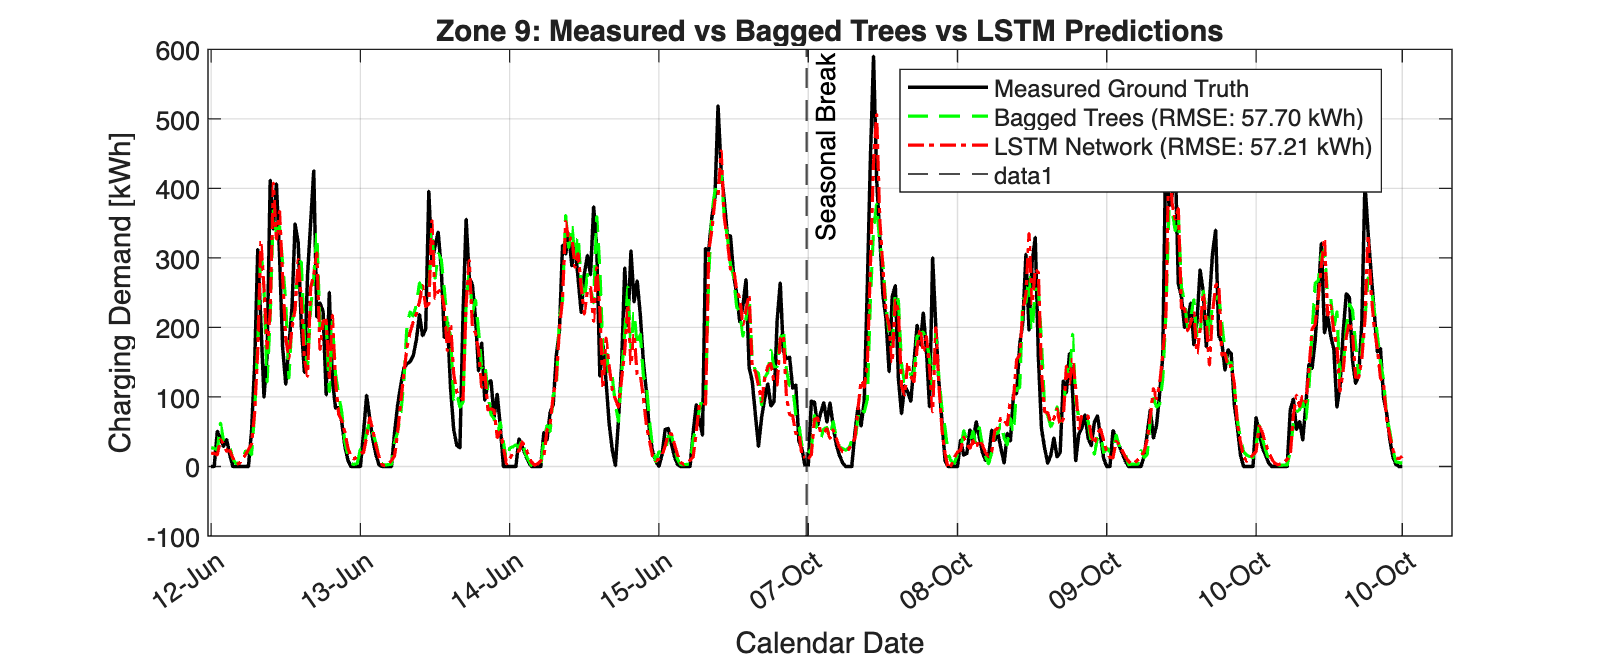

gapIndices = find(diff(testTable.datetime) > minutes(30));
numSamples = height(testTable);
xVec = 1:numSamples;

xPlot = xVec;
yTestPlot = yTest;
yRegPlot  = yPredReg;
yLSTMPlot = yPredLSTM;

for g = numel(gapIndices):-1:1
    idx = gapIndices(g);
    xPlot = [xPlot(1:idx), idx + 0.5, xPlot(idx+1:end)];
    yTestPlot = [yTestPlot(1:idx); NaN; yTestPlot(idx+1:end)];
    yRegPlot  = [yRegPlot(1:idx);  NaN; yRegPlot(idx+1:end)];
    yLSTMPlot = [yLSTMPlot(1:idx); NaN; yLSTMPlot(idx+1:end)];
end

figure("Position", [100, 100, 1100, 450])
plot(xPlot, yTestPlot, "k-", LineWidth=1.3, DisplayName="Measured Ground Truth")
hold on
plot(xPlot, yRegPlot, "g--", LineWidth=1.2, ...
    DisplayName=sprintf("Bagged Trees (RMSE: %.2f kWh)", rmseReg))
plot(xPlot, yLSTMPlot, "r-.", LineWidth=1.2, ...
    DisplayName=sprintf("LSTM Network (RMSE: %.2f kWh)", rmseLSTM))

for g = 1:numel(gapIndices)
    xline(gapIndices(g) + 0.5, "k--", "Seasonal Break", LabelVerticalAlignment="top", LineWidth=0.8)
end

tickIdx = unique([1:48:numSamples, numSamples]);
xticks(tickIdx)
xticklabels(string(testTable.datetime(tickIdx), "dd-MMM"))
xtickangle(35)
xlabel("Calendar Date")
ylabel("Charging Demand [kWh]")
title(sprintf("Zone %d: Measured vs Bagged Trees vs LSTM Predictions", zoneId))
legend("Location", "best")
grid on

## Visual Storytelling: Error Distribution and Performance Summary

Display residual distributions and metric comparison in a 1x2 panel layout.

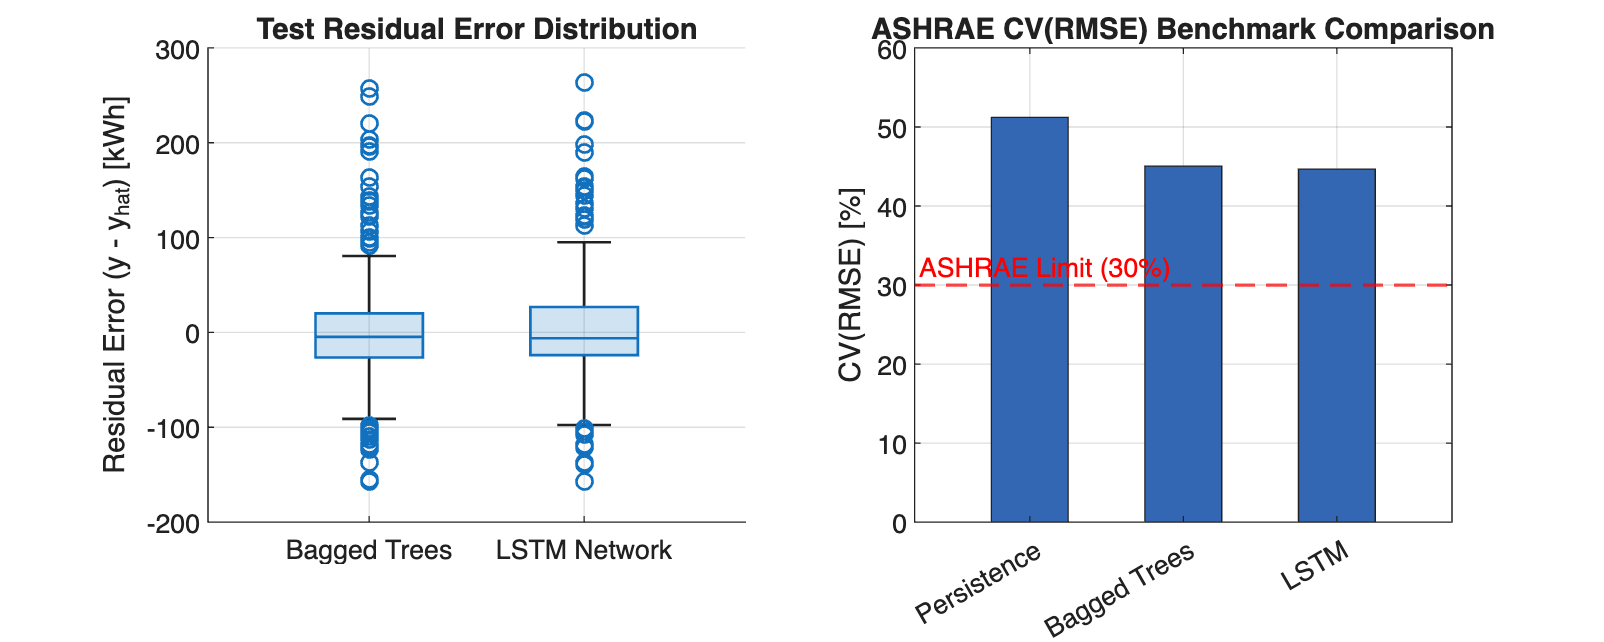

figure("Position", [100, 100, 1000, 400])

subplot(1, 2, 1)
residualsReg = yTest - yPredReg;
residualsLSTM = yTest - yPredLSTM;
boxchart([residualsReg, residualsLSTM])
xticklabels(["Bagged Trees", "LSTM Network"])
ylabel("Residual Error (y - y_{hat}) [kWh]")
title("Test Residual Error Distribution")
grid on

subplot(1, 2, 2)
modelCategories = categorical(["Persistence", "Bagged Trees", "LSTM"]);
modelCategories = reordercats(modelCategories, ["Persistence", "Bagged Trees", "LSTM"]);
bar(modelCategories, [cvLazy, cvReg, cvLSTM], 0.5, "FaceColor", [0.2 0.4 0.7])
ylabel("CV(RMSE) [%]")
title("ASHRAE CV(RMSE) Benchmark Comparison")
yline(30, "r--", "ASHRAE Limit (30%)", LabelHorizontalAlignment="left", LineWidth=1.2)
grid on